# Custom Documentation Structure

## Introduction

The menu on the left side of the documentation, which is used to access the specific pages, is called the "table of content" or "toc". By default, the toc structure is mirrored from the folder structure. However, it might be advantageous to merge folder contents, rename or move headings, or exclude folders alltogether. This can be done by setting a cell in opts.toc. The cell is defined as follows:

opts.toc = {}; % default for mirroring existing folder structure
opts.toc = {"customHeading", ["Folder1"] , {subcell} }; % custom toc structure

### First Column: Heading Names

Each row of the first column contains names, which will be headings in the toc structure.

Custom rule: All undefined folders will be put as subheadings of the first toc element (opts.toc{1,1}).

### Second Column: Folder Names

The cells of the second column contain a string (array) which defines specific folders that should be merged into the current toc heading. The current toc heading is the name defined in the first column of the same row. Subfolders of a specified folder will also be assigned as a substructure of the new heading. If the second column is left empty, then the heading will be generated, but no files will be assigned to it. 

Tips:

Note that the folders itself will be "dissolved", and only the contained files and subfolders will be listed under the current heading. Please make sure to use unique folder names, because otherwise m2doc might merge the wrong folders.

Example:

customCell = {"m2doc_help", ["help","Templates"], {}}

This will assign the folders (+their files and subfolders) "help" and "Templates" to the heading "m2doc_help". 

### Third Column: (optional) Sub Cells

To define a substructure of a toc heading, you can assign a cell which contains the three columns. If no custom subcell is wanted, please enter an empty cell with '{}'.

## Example: Custom Toc

opts.toc        = {"Welcome_to_m2doc",  "/",    {};...
                   "Additional",        "help", {}};
opts.toc{1,3}   = {"Dummy", "@Dummy", {};
                    "MFile", "@MFile", {};
                    "createDoc", ["@createDoc" "@TemplateHTML"], {}};  

### Effect

If no custom opts.toc is set, the toc structure is 'mirrored' from the folder structure:

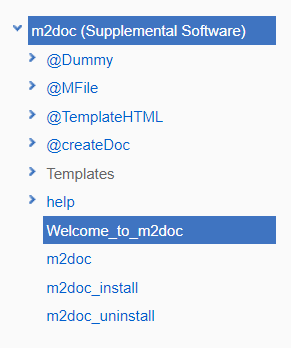

The toc structure above creates this structure:

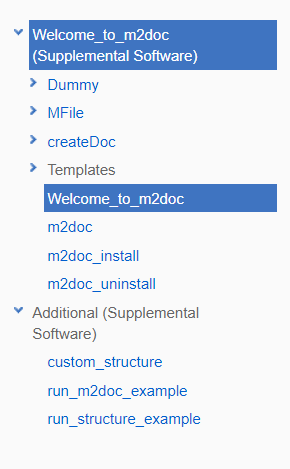

### Execute example code

[Click here to generate the m2doc documentation with the structure defined above](matlab:run("run_structure_example.m")). Make sure that the m2doc toolbox was added to the matlab search path.